% Create individual element
fc = 915e6;
c = physconst('lightspeed');
lambda = c/fc;

dx = 0.5*lambda;  %0.485
d = dipole;
d.Length = 0.157;
d.Width = 0.002;
d.TiltAxis = 'Y';
d.Tilt = 90;
N = 4;

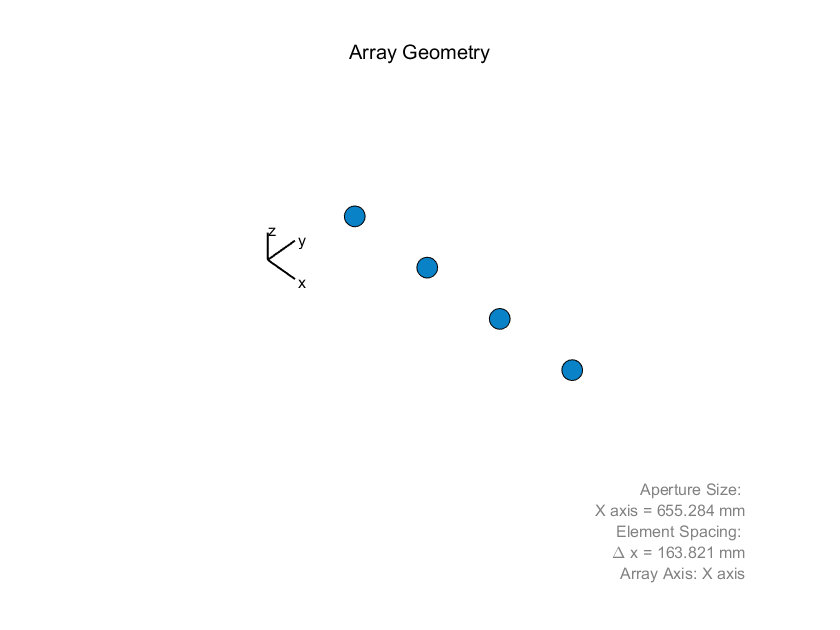

% Create array
array = phased.ULA;
array.Element = d;
array.ElementSpacing = dx;
array.NumElements = N;
array.ArrayAxis = 'x';
viewArray(array);

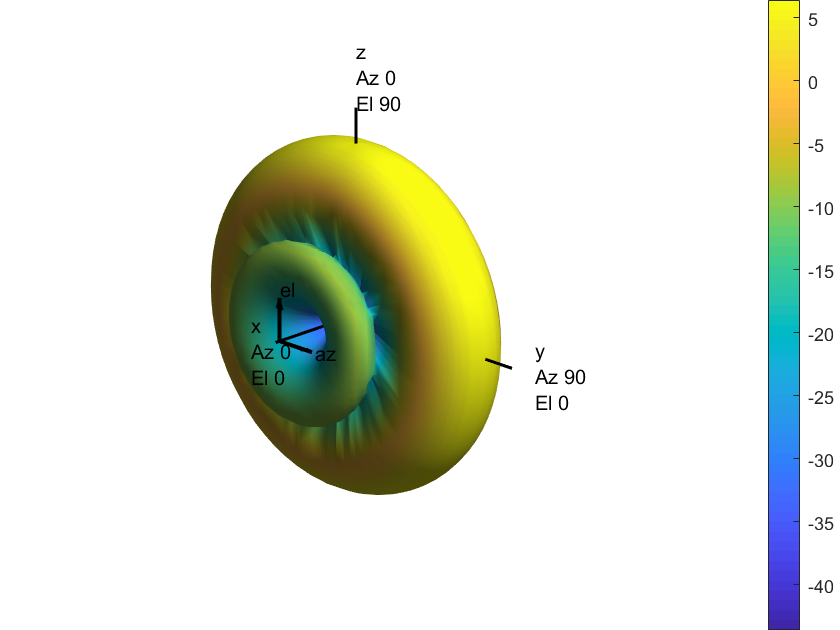

pattern(array,fc);

% sterring vector
steervec = phased.SteeringVector('SensorArray',array);
% ang = [30; 20]; % direction of 30 degrees azimuth and 20 degrees elevation
ang = [45; 0];
sv = steervec(fc,ang);

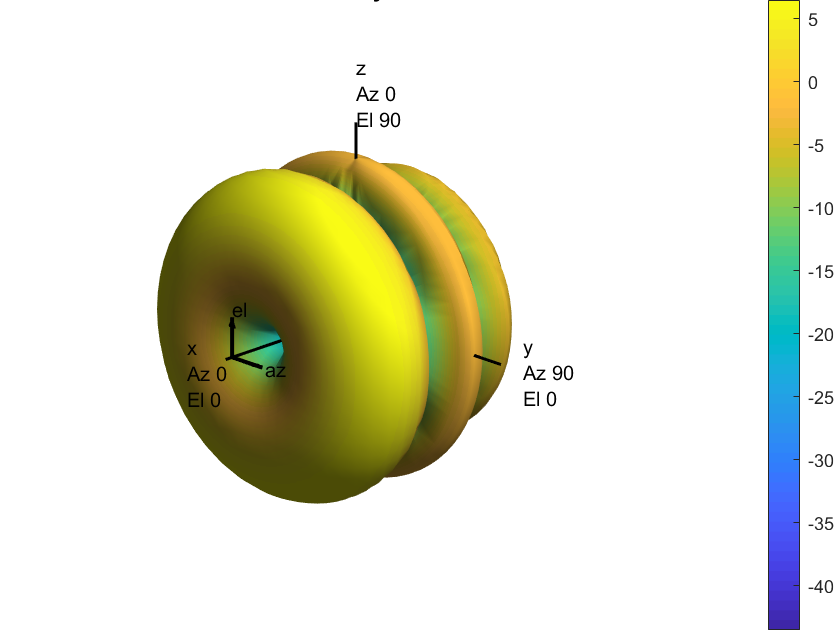

pattern(array,fc,'Weights',sv)

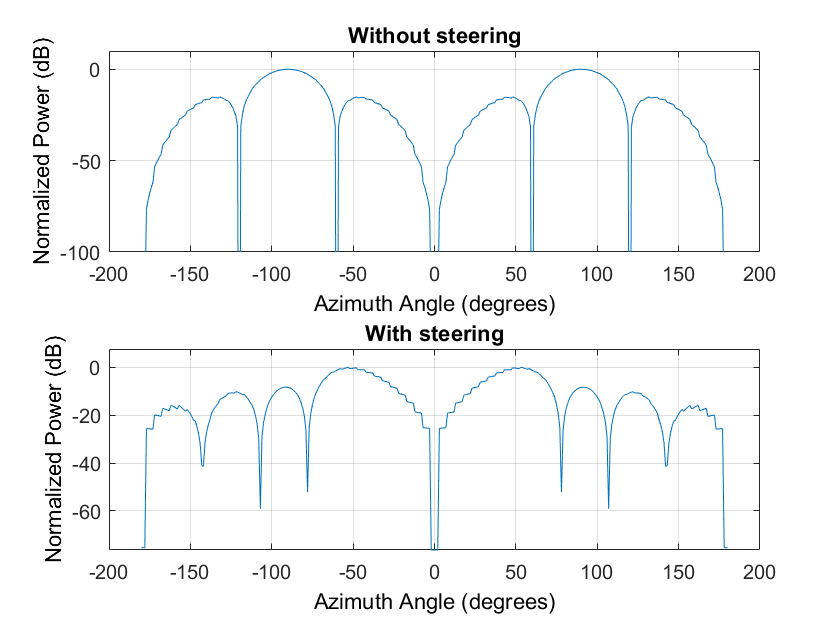

subplot(211)
pattern(array,fc,-180:180,0,'CoordinateSystem','rectangular', ...
    'PropagationSpeed',c,'Type','powerdb')
title('Without steering')
subplot(212)
pattern(array,fc,-180:180,0,'CoordinateSystem','rectangular', ...
    'PropagationSpeed',c,'Type','powerdb','Weights',sv)
title('With steering')